clc;
clear;
syms x;

a = 1;
b = 0;
c =x

$$c = x$$


%f(x) = 4 * x^2 - 2 * x - 4;
f =x;

P = 1; % Only works till P = 6  % Gauss points restriction
% P Order of Interpolation Function for element
ndofel = P+1;
% No of elements
e = 4;

% domain of X
x0 = 0;
xL = 1;

L = xL; % Length


% Get the handle of the command window
commandwindow;


% Prompt the user to input boundary conditions at x0
prompt_x0 = 'Enter the type of boundary condition at x0 (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_x0 = input(prompt_x0);

switch type_x0
    case 1
        u0 = input('Enter the Dirichlet value u at x0: ');
    case 2
        Q0 = input('Enter the Neumann value AE*(du/dx) at x0: ');
    case 3
        K0 = input('Enter the spring constant K at x0: ');
        Del0 = input('Enter the spring displacement Del at x0: ');
    otherwise
        error('Invalid boundary condition type at x0');
end


% Prompt the user to input boundary conditions at xL
prompt_xL = 'Enter the type of boundary condition at xL (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_xL = input(prompt_xL);

switch type_xL
    case 1
        uL = input('Enter the Dirichlet value u at xL: ');
    case 2
        P1 = input('Enter the Neumann value AE*(du/dx) at xL: ');
    case 3
        K1 = input('Enter the spring constant K at xL: ');
        Del1 = input('Enter the spring displacement Del at xL: ');
    otherwise
        error('Invalid boundary condition type at xL');
end

% Prompt the user to input information about a point load
prompt_pointLoad = 'Is there a point load present? (1.yes, 2.no): ';
pointLoadResponse = input(prompt_pointLoad); % Numeric input

switch pointLoadResponse
    case 1
        PL1 = input('Enter the value of the point load: ');
        PL1_loc = input('Enter the Point Load Location: ');
    case 2
        disp('No point load present, continuing with the rest of the code.');
    otherwise
        error('Invalid response for the presence of a point load. Please enter 1.yes or 2.no.');
end

% Continue with the remaining code...

if exist('PL1_loc', 'var') && exist('PL1', 'var')
    F_location = PL1_loc;  
    x_vector = GlobalLocation(x0, xL, P, e);
    
    [incremented_e, decremented_e, valuePL] = adjust_e(x_vector, P, x0, xL, F_location, e);
     if valuePL == 1

        % Continue with the rest of the code as usual if valuePL is 1.
        adjusted_e = choose_e(incremented_e, decremented_e, e);
        x_vector1 = GlobalLocation(x0, xL, P, adjusted_e);
        PL1_index = find_indices(x_vector1, F_location);
        disp(['Indices where x_vector == F_location: ', num2str(PL1_index)]);

    elseif valuePL == 2
       
        prompt_adjust = ['For given Point load location and element number Their is No nodal point to keep Point load' ...
            ' Do you want to adjust the element value? (1.yes, 2.no): '];
        adjustResponse = input(prompt_adjust);
        
        if adjustResponse == 1
            adjusted_e = choose_e(incremented_e, decremented_e, e);
            disp(['Adjusted New elements is: ', num2str(adjusted_e)]);
            x_vector1 = GlobalLocation(x0, xL, P, adjusted_e);
            PL1_index = find_indices(x_vector1, F_location);
            disp(['Indices where x_vector == F_location: ', num2str(PL1_index)]);

        elseif adjustResponse == 2

            disp('Exiting the program.');
            return; % This will exit the script

        else
            error('Invalid response. Please enter 1 for yes or 2 for no.');
        end
    else
        error('Unexpected valuePL. Expected values are 1 or 2.');
     end
end

F_location is present in x_vector.


Indices where x_vector == F_location: 3




if exist('adjusted_e', 'var')
    e = adjusted_e;
end




[K_global_D_bc, Fv, S, X_nodes] = FEM_Processor(P, e, L, a, b, c, f);


Gv = sym(zeros(S, 1));
Sv = sym(zeros(S, 1));


if exist('PL1_index', 'var') && exist('PL1_loc', 'var') && exist('PL1', 'var')
    Gv(PL1_index) = PL1
end

$$Gv = \left(\begin{array}{c} 0\\ 0\\ 10\\ 0\\ 0 \end{array}\right)$$



% For X0 left node we need to add correction factor
if exist('Q0', 'var') 
    Gv(1) = -Q0;   % Correction factor Added
end

if exist('K0', 'var') && exist('Del0', 'var')
    Sv(1) = -K0 * Del0;    % Correction factor Added
    K_global_D_bc(1, 1) = K_global_D_bc(1, 1) + K0;
end


if exist('P1', 'var') 
    Gv(end) = P1;
end

if exist('K1', 'var') && exist('Del1', 'var')
    Sv(end) = K1 * Del1;  
    K_global_D_bc(end, end) = K_global_D_bc(end, end) + K1;
end
Gv= Gv*a

RHS = Fv + Gv + Sv;


% Handle boundary conditions at x0
if exist('u0', 'var') 
    K_global_D_bc(1, :) = [1, zeros(1, S-1)];  % u0 = 0
    RHS(1) = u0;  % RHS of equation
end

% Handle boundary conditions at xL
if exist('uL', 'var') 
    K_global_D_bc(end, :) = [zeros(1, S-1), 1];  % uL = 0
    RHS(end) = uL;  % RHS of equation
end  

K_global_D_bc

K_global_D_bc =     1.0000         0         0         0         0
   -4.0052    7.9583   -4.0156         0         0
         0   -4.0156    7.9167   -4.0260         0
         0         0   -4.0260    7.8750   -4.0365
         0         0         0   -4.0365    3.9219


RHS

$$RHS = \left(\begin{array}{c} 0\\ -\frac{1}{16}\\ \frac{79}{8}\\ -\frac{3}{16}\\ \frac{949}{96} \end{array}\right)$$


u_nodes = double(K_global_D_bc \ RHS);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


myTable = table(X_nodes, u_nodes, 'VariableNames', {'Nodal Location', 'u node value'});
disp(myTable);

    Nodal Location    u node value
    ______________    ____________

            0                 0   
         0.25             6.785   
          0.5            13.462   
         0.75            17.252   
            1            20.276   



disp("-------------------------------------------------------------")

-------------------------------------------------------------



syms x  u_e(x)
%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2)+b*diff(u_e,x,1)+c*u_e == f;

d_ue(x)= diff(u_e,x);


if exist('Q0', 'var') 
    ic0=d_ue(x0) == Q0;  

elseif exist('K0', 'var') && exist('Del0', 'var')
    ic0=d_ue(x0) == K0 * (Del0+u_nodes(1));    
else
    ic0=u_e(x0) == u0;
end

if exist('P1', 'var') 
    icL=d_ue(xL) == P1;  

elseif exist('K1', 'var') && exist('Del1', 'var')
    icL=d_ue(xL) == K1 * (Del1-u_nodes(end));    
else
    icL=u_e(xL) == uL;
end

u_exact = dsolve(deqn,[ic0 icL]);
exact_sol_f = u_exact
%----------------------------------------------------------------------------------
clear u_e(x)

$$exact\_sol\_f = \begin{array}{l} 1-\frac{3^{2/3}\,\text{airy}\left(2,-x\right)\,\left(3\,\Gamma (\frac{2}{3})\,\text{airy}\left(1,-1\right)-10\,3^{1/3}\right)}{3\,\sigma_{1}}-\frac{\text{airy}\left(0,-x\right)\,\left(10\,\sqrt{3}-3^{2/3}\,\Gamma (\frac{2}{3})\,\text{airy}\left(3,-1\right)\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{3}\,\text{airy}\left(1,-1\right)-\text{airy}\left(3,-1\right) \end{array}$$


u_nodes =  u_nodes';
X_nodes = X_nodes';

% Initialize storage for table contents
element_numbers = (1:e)';
interpolating_functions = cell(e, 1);
ranges = cell(e, 1);


i =1;
% Initialize storage for u' values
u_prime_values = zeros(S,1)';
index =1;

for element = 1:ndofel-1:S-1

    start_index = element;
    end_index = element + ndofel-1;
    x_node_loc = X_nodes(start_index:end_index); % Extract node locations for the current element
    u_node_value = u_nodes(start_index:end_index); % Extract node values for the current element
    
    % Perform Lagrange interpolation (assuming you have a function that does this)
    [~, Lagrange_polynomial] = lagrange_interpolation(ndofel, x_node_loc, u_node_value);
    
    % Derive u' from the Lagrange polynomial
    Lagrange_derivative = diff(Lagrange_polynomial, x);
    
    % Evaluate u' at all nodal points within the element's range except for the last point
    for xi = x_node_loc(1:end-1)
        u_prime_value = double(subs(Lagrange_derivative, x, xi));
        u_prime_values(index) = u_prime_value;
        index = index+1;
    end

    if e == i
        u_prime_values(end) = double(subs(Lagrange_derivative, x, X_nodes(end)));
    end


    % Store the results
    interpolating_functions{i} = char(Lagrange_polynomial);
    ranges{i} = sprintf('[%g, %g]', x_node_loc(1), x_node_loc(end));

    i = i+1;
end


% Create and display the table
T = table(element_numbers, interpolating_functions, ranges, ...
          'VariableNames', {'Element Number', 'Interpolating Function', 'Range'});
disp(T);

    Element Number                             Interpolating Function                                   Range     
    ______________    _________________________________________________________________________    _______________

          1           {'(3819606055616117*x)/140737488355328'                                 }    {'[0, 0.25]'  }
          2           {'(3759010614192551*x)/140737488355328 + 30297720711783/281474976710656'}    {'[0.25, 0.5]'}
          3           {'(1066595906714257*x)/70368744177664 + 414029130368955/70368744177664' }    {'[0.5, 0.75]'}
          4           {'(851353783681851*x)/70368744177664 + 1150921445286519/140737488355328'}    {'[0.75, 1]'  }





myTable = table(X_nodes', u_nodes',u_prime_values', 'VariableNames', {'Nodal Location', 'u node value','du/dx'});
disp(myTable);

    Nodal Location    u node value    du/dx 
    ______________    ____________    ______

            0                 0        27.14
         0.25             6.785       26.709
          0.5            13.462       15.157
         0.75            17.252       12.098
            1            20.276       12.098



disp("-------------------------------------------------------------")

-------------------------------------------------------------


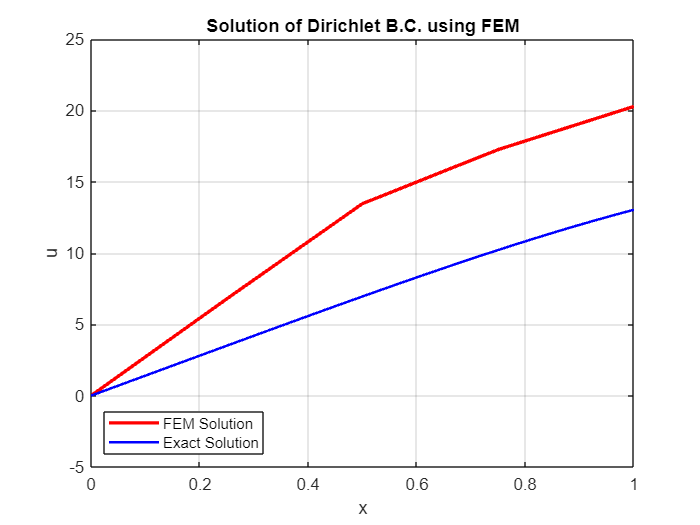


%Plot the FDM Solution and the actual solution
figure;
plot(X_nodes, u_nodes, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f,[x0 xL] ,"b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;


dexact_sol_f = diff(exact_sol_f,x)

$$dexact\_sol\_f = \begin{array}{l} \frac{\text{airy}\left(1,-x\right)\,\left(10\,\sqrt{3}-3^{2/3}\,\Gamma (\frac{2}{3})\,\text{airy}\left(3,-1\right)\right)}{\sigma_{1}}+\frac{3^{2/3}\,\text{airy}\left(3,-x\right)\,\left(3\,\Gamma (\frac{2}{3})\,\text{airy}\left(1,-1\right)-10\,3^{1/3}\right)}{3\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{3}\,\text{airy}\left(1,-1\right)-\text{airy}\left(3,-1\right) \end{array}$$

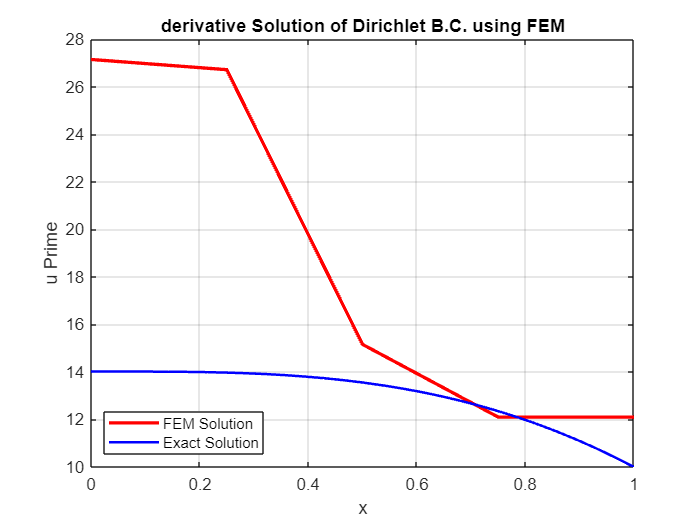


%Plot the FDM Solution and the actual solution
figure;
plot(X_nodes, u_prime_values, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, dexact_sol_f,[x0 xL] ,"b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u Prime");
title("derivative Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;

function [L,L_simplified] = lagrange_interpolation(n,x_data, y_data)


    % here L is Lagrange polynomial
    syms x;
    L = 0;   % Initialize Lagrange polynomial
    
    % Creating symbolic variables for y_j and x_j
    y_string = sym('y', [1 n]);  % for Visualizing deriving Formula using symoblic math
    x_string = sym('x', [1 n]);
    
    % Generating Lagrange interpolating polynomial
    for j = 1:n
        % Compute the product term for each j
        product_term = 1;
        for k = 1:n
            if k ~= j
                product_term = product_term * (x - x_string(k)) / (x_string(j) - x_string(k));
            end
        end
    
        % Updating Lagrange polynomial
        L = L + y_string(j) * product_term;
    end

    L_substitute = subs(L, [x_string, y_string], [x_data, y_data]);

    L_simplified = simplify(L_substitute);
end


function adjusted_e = choose_e(incremented_e, decremented_e,e)
    if incremented_e ~= 0 && decremented_e ~= 0
        adjusted_e = max(incremented_e, decremented_e); %here Min or Max You should Decide
    elseif incremented_e == 0
        adjusted_e = e;
    elseif decremented_e == 0
        adjusted_e = e;
    else
        error('Both incremented_e and decremented_e are zero. Cannot choose a valid e value.');
    end
end
function x_vector = GlobalLocation(x0,x1,P,e)
     h = (x1 - x0) / e;
     x_vector = x0:(h / P):x1; %formula i am using

end

function indices = find_indices(x_vector, F_location)
    for i = 1:length(x_vector)
        if x_vector(i) == F_location
            indices = i;
            break;
        end
    end
end

function [incremented_e, decremented_e,valuePL] = adjust_e(x_vector,P, x0, x1, F_location, e)
    %h = (x1 - x0) / e;
    %x_vector = x0:(h / P):x1; formula i am using

    if any(x_vector == F_location)
        disp('F_location is present in x_vector.');
        incremented_e = 0;
        decremented_e = 0;
        valuePL = 1;
    else
        disp('For given Point load location and element number Their is No nodal point to keep Point load');
        disp("Instead Try adjusted Element value given below");
        disp("--------------------------------------------------------------------------------------------");
        e_adjusted = e;
        e_increment = 1; % small increment or decrement value for n
        valuePL = 2;


        found_incremented = false;
        found_decremented = false;

        while ~(found_incremented && found_decremented)
            % Increment e
            e_incremented = e_adjusted + e_increment;
            h_incremented = (x1 - x0) / e_incremented;
            x_vector_incremented = x0:(h_incremented / P):x1;

            % Check if F_location is present in the incremented x_vector
            if any(x_vector_incremented == F_location)
                found_incremented = true;
                disp(['Incremented e value: ', num2str(e_incremented)]);
                incremented_e = e_incremented;
            end

            % Decrement n
            e_decremented = e_adjusted - e_increment;
            h_decremented = (x1 - x0) / e_decremented;
            x_vector_decremented = x0:(h_decremented / P):x1;

            % Check if F_location is present in the decremented x_vector
            if any(x_vector_decremented == F_location)
                found_decremented = true;
                disp(['Decremented e value: ', num2str(e_decremented)]);
                decremented_e = e_decremented;
            end

            % If F_location is not found for either increment or decrement, update n_adjusted for next iteration
            if ~(found_incremented && found_decremented)
                e_adjusted = e_adjusted + e_increment;
            end
        end

        if ~(found_incremented || found_decremented)
            disp('F_location is not present in x_vector for both incremented and decremented e values.');
            incremented_e = 0;
            decremented_e = 0;
        end
    end
end

